# Data Processing and Graph Generation for Membrane Fouling Research

### Step 1:

This chunk loads the data from 2 sources. The function load_trials pulls the data from the indivual .mat files for each experiment and compiles it into a single matlab struct. Each field in the struct is a different variable and each row represents an experiment. The second source is from the results table on the google drive. The load_results function adds additional fields to the struct for additional data.

%Load Data from Trial .mat files and Results .csv files
trial = load_trials();
trial = load_results(trial);

results = 19×15 table
    TrialNumber    Salinity    ConductivityTheoretical    ConductivityStart    ConductivityEnd    StartTime     StartDate     Pressure_psi_    PumpPower    Good           Reason               Researcher        ScaleTime1_min_    ScaleTime2_min_    BatchFlowrate
    ___________    ________    _______________________    _________________    _______________    __________    __________    _____________    _________    ____    ____________________    __________________    _______________    ___

### Step 2:

This chunk process the data by calculating important values and applying lowpass filters to some of the data to remove noise. 

%Process Data and Add Calculations
trial = filter_and_process(trial);

vel =          0
    0.0937
    0.0936
    0.0949
    0.0928
    0.0915
    0.0917
    0.0910
    0.0909
    0.0918


vel =          0
    0.0593
    0.0599
    0.0620
    0.0591
    0.0619
    0.0613
    0.0612
    0.0618
    0.0582


vel =          0
    0.0668
    0.0675
    0.0670
    0.0673
    0.0667
    0.0633
    0.0650
    0.0679
    0.0654



vel =

     []



vel =          0
    0.0746
    0.0731
    0.0724
    0.0718
    0.0720
    0.0722
    0.0714
    0.0737
    0.0678


vel =          0
    0.0684
    0.0658
    0.0695
    0.0675
    0.0677
    0.0672
    0.0677
    0.0675
    0.0701



vel =

     []


vel =

     []


vel =

     []



vel =          0
    0.0696
    0.0700
    0.0702
    0.0742
    0.0713
    0.0725
    0.0714
    0.0720
    0.0676


vel =          0
    0.0656
    0.0635
    0.0669
    0.0643
    0.0645
    0.0625
    0.0627
    0.0682
    0.0674


vel =          0
    0.0626
    0.0644
    0.0664
    0.0644
    0.0737
    0.0700
    0.0700
    0.0700
    0.0700


vel =          0
    0.0624
    0.0656
    0.0672
    0.0672
    0.0657
    0.0671
    0.0655
    0.0645
    0.0642


vel =          0
    0.0627
    0.0661
    0.0656
    0.0652
    0.0639
    0.0611
    0.0648
    0.0668
    0.0620


vel =          0
    0.0516
    0.0541
    0.0546
    0.0209
    0.0151
    0.0178
    0.0197
    0.0405
    0.0527


vel =          0
    0.0633
    0.0624
    0.0639
    0.0615
    0.0618
    0.0603
    0.0632
    0.0655
    0.0623


vel =          0
    0.0162
    0.0137
    0.0144
    0.0174
    0.0177
    0.0156
    0.0164
    0.0159
    0.0122


vel =          0
    0.0949
    0.0940
    0.0949
    0.0949
    0.0956
    0.0954
    0.0956
    0.0946
    0.0944


vel =          0
    0.0796
    0.0799
    0.0766
    0.0783
    0.0787
    0.0780
    0.0808
    0.0826
    0.0798


vel =          0
    0.0939
    0.0948
    0.0955
    0.0949
    0.0942
    0.0940
    0.0939
    0.0952
    0.0954


vel =          0
    0.0937
    0.0936
    0.0949
    0.0928
    0.0915
    0.0917
    0.0910
    0.0909
    0.0918


vel =          0
    0.0775
    0.0774
    0.0788
    0.0795
    0.0794
    0.0814
    0.0779
    0.0769
    0.0792


vel =          0
    0.0800
    0.0795
    0.0822
    0.0791
    0.0798
    0.0838
    0.0804
    0.0772
    0.0781


vel =          0
    0.0716
    0.0706
    0.0710
    0.0719
    0.0729
    0.0718
    0.0724
    0.0716
    0.0732


vel =          0
    0.0719
    0.0701
    0.0666
    0.0686
    0.0723
    0.0712
    0.0686
    0.0701
    0.0724


vel =          0
    0.0715
    0.0700
    0.0688
    0.0697
    0.0689
    0.0733
    0.0703
    0.0714
    0.0725


Trial #1
Trial #2
Trial #3
Trial #4
Trial #5
Trial #6
Trial #7
Trial #8
Trial #9
Trial #10
Trial #11
Trial #12
Trial #13
Trial #14
Trial #15
Trial #16
Trial #17
Trial #18
Trial #19
Trial #20
Trial #21
Trial #22
Trial #23
Trial #24
Trial #25
Trial #26


### Step 3:

Once the data is loaded and processed it can now be analyzed and plotted. All of the data lives in a matlab sturct called trial. This struct can be looked at to see summative variables like mean of batch flowrates and concentration at the membrane. 

#### Matrix Variable:

batch_flowrate_list: Raw flowrate data with units of mL/min

permeate_flowrate_list: Raw flowrate data with units of mL/min

time_list: time data from experiment in seconds

permeateFlux: Flux through membrane with units of L/m^2/hr

membraneConcentration: Concentration at Membrane with units of M

batchFlowrateFiltered: lowpassed flowrate data with units of mL/min

permeateFlowrateFiltered: lowpassed flowrate data with units of mL/min

membraneConcentrationFiltered: lowpassed concentration data with units of M

permeateFluxFiltered: lowpassed concentration data with units of L/m^2/hr

#### Numeric Values:

ConductivityStart: Conductivity at the start of the experiment with units of uS

ConductivityEnd: Conductivity at the end of the experiment with units of uS

ScaleTime1: Time it takes to scale with units of min

ScaleTime2: Time it takes to do second drop in flux with units of min

batchFlowMean: Mean batch flowrate of system with units of mL/min

batchFlowPrescaleMean: Mean batch flowrate before scaling with units of mL/min

concentration: Concentration at start of experiment with units of M

membraneConcentrationMean: Mean concentration at the membrane with units of M

membraneConcentrationPrescaleMean: Mean concentration before scaling with units of M

#### Non-numeric Values:

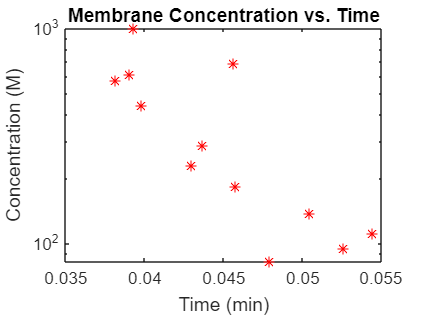

%plot all permeate flow rates
clf;
semilogy(extractfield(trial, 'membraneConcentrationPrescaleMean'),extractfield(trial, 'ScaleTime1'),'r*')
xlabel("Time (min)")
ylabel("Concentration (M)")
title('Membrane Concentration vs. Time')

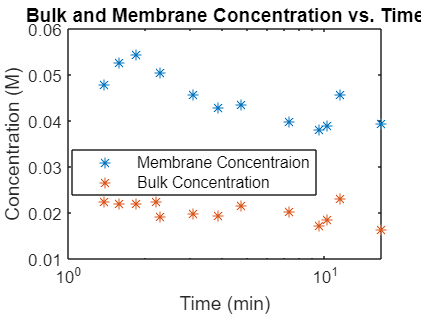

clf;
semilogx(extractfield(trial, 'ScaleTime1')/60, [extractfield(trial, 'membraneConcentrationPrescaleMean'); extractfield(trial, 'concentration')],'*')
xlabel("Time (min)")
ylabel("Concentration (M)")
legend('Membrane Concentraion', 'Bulk Concentration','Location', 'best')
title('Bulk and Membrane Concentration vs. Time')

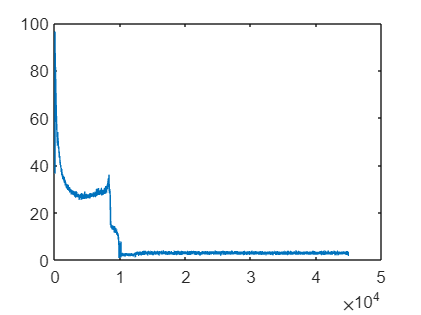

plot(trial(15).time_list(1:end-1), trial(15).permeateFluxFiltered)

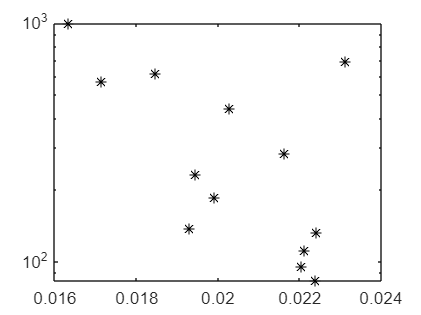

clf;
semilogy(extractfield(trial, 'concentration'),extractfield(trial, 'ScaleTime1'),'k*')

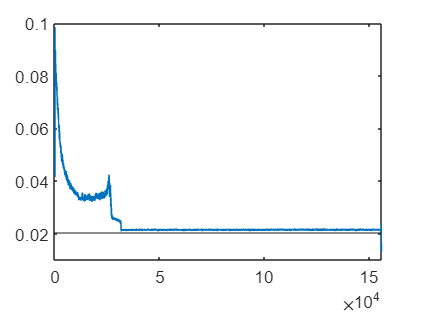

Error using ylim
Limits must be a 2-element vector of increasing numeric values.

plot(trial(2).time_list(1:end-1), trial(2).membraneConcentrationFiltered)
yline(trial(2).concentration)
ylim([0:.1])

%get average batchflow rate and permeate flow rate
for i = 1:25
    trial(i).batch_flowrate_avg_preScale
end

plot(trial(26).time_list(1:end-1), trial(26).permeate_flowrate_list)

hold on
plot(trial(2).time_list(1:end-1), [trial(2).permeate_flowrate_list, trial(2).permeateFlowrateFiltered])
xlim([0 trial(2).ScaleTime1*60+360])